# 'lathe' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'lathe.pov', 'image_file', 'lathe.png');
    pl.include("shapes");
    pl.include("glass");
    
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 35, 'location', [23 7 7], 'look_at', [0 4 1.5], 'type', 'perspective');
    
    % Light
    pl.light('location', [2.5 4.7 12], 'color', [0.2 0.2 0.2]);
    pl.light('location', [8 2.7 12],   'color', [0.2 0.2 0.2]);
    pl.light('location', [7.5 7.5 12], 'color', [0.1 0.1 0.1]);
    pl.light('location', [23 7 7],     'color', [0.1 0.1 0.1]);

    % Walls
    tex_plane  = pl.declare("tex_plane", pl.texture('pigment_odd', [1.5 1.5 1.5], 'pigment_even', [0.1 0.1 0.1]));
    pl.plane('normal', [1,0,0], 'distance', -10, 'texture', tex_plane','translate', [0 0 1]);
    pl.plane('normal', [0,0,1], 'distance', 0,   'texture', tex_plane');
    
    % Profile
    points = [0.00 0.00; 0.35 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53];

    % Bottle 1
    tex_bottle1 = pl.declare('tex_bottle1', pl.texture('base', 'T_Vicksbottle_Glass', 'pigment', [17.5 4.2 3.2], ...
                             'finish', 'ambient 0.001 diffuse 0.2 reflection 0.04 specular 24.4 roughness 0.0004'));
    pl.lathe('points', points,...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', tex_bottle1,...
            'scale', [4 4 4], 'rotate', [ 90 0 0], 'translate', [7 2.7 0]);
    
    % Bottle 2
    tex_bottle2 = pl.declare('tex_bottle3', pl.texture('base', 'T_Vicksbottle_Glass', 'pigment', [2.8 3.8 0.1], ...
                             'finish', 'ambient 0.001 diffuse 0.3 reflection 0.04 specular 24.4 roughness 0.0004'));
    pl.lathe('points', points,...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', tex_bottle2,...
            'scale', [2.7 3.7 2.7], 'rotate', [ 90 0 0], 'translate', [6.5 7.5 0]);
    
    % Bottle 3
    tex_bottle3 = pl.declare('tex_bottle3', pl.texture('base', 'T_Vicksbottle_Glass', 'pigment', [4.8 1.8 0], ...
                             'finish', 'ambient 0.001 diffuse 0.3 reflection 0.04 specular 24.4 roughness 0.0004'));
    pl.lathe('points', points,...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', tex_bottle3,...
            'scale', [5 3 4], 'rotate', [ 90 0 0], 'translate', [1.5 4.7 0]);

pl.scene_end();

#### Render and display

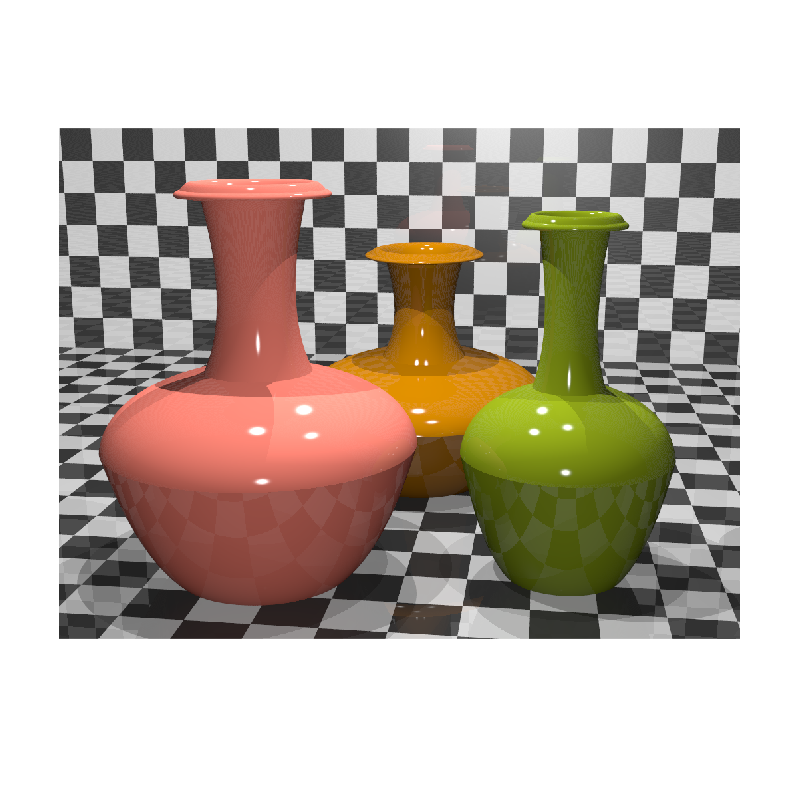

img = pl.render();
imshow(img);

####  Elapsed time

toc

Elapsed time is 8.990180 seconds.
